% Stage 1: Load MeanRGB and CosRGB from 4 image files.

%dir = 'canoncut'
%file = 'set4/rot';
%div = 1.0;

dir = 'cut';
file = 'potdng';
div = 255.0;

[Y, X, ~] = size(imread(strcat(dir, '/', file, '0.tif')));
ims = gpuArray(zeros(4, Y, X, 3, 'double'));
clear Y;
clear X;

for x=0:3
    deg = num2str(45 * x);
    ims(x+1, :, :, :) = rgb2lin(double(imread(strcat(dir, '/', file, deg, '.tif'))) ./ div);
end

clear deg;
clear x;
clear dir;
clear div;

imsfft = fft(ims, 4, 1) * 0.5;
clear ims;

MeanRGB = squeeze(abs(imsfft(1, :, :, :))) * 0.5; % 0.5 * Diffuse + 0.5 * Perp + 0.5 * Parallel
CosRGB = squeeze(abs(imsfft(2, :, :, :))); % 0.5 * (Perp - Parallel)
clear imsfft;

imshow(lin2rgb(gather(MeanRGB)));
imshow(lin2rgb(gather(CosRGB)));

% Stage 2: Computing an initial estimate for the Diffuse and Specular components.

[qyTotal, qxTotal, ~] = size(MeanRGB);
divCount = 4;
qyPart = qyTotal / divCount;
qxPart = qxTotal / divCount;

As = gpuArray(ones([qyPart qxPart 25 2]));
bs = gpuArray(zeros([qyPart qxPart 25 1]));

sigma_spatial = 1.0;
sigma_tonal = 0.02;

SpecularFactor = gpuArray(zeros([qyPart qxPart 3]));

for c = 1:3
    tic;
    for qy = 0:(divCount-1)
        yOffset = qyPart * qy;
        yCoords = (yOffset+1):(yOffset+qyPart);
        for qx = 0:(divCount-1)
            xOffset = qxPart * qx;
            xCoords = (xOffset+1):(xOffset+qxPart);
            
            % Fill matrix.
            for i = 1:25
                yDiff = floor((i - 1) / 5) - 2;
                xDiff = mod(i - 1, 5) - 2;
                
                yCoordsShift = max(1, min(qyTotal, yCoords + yDiff));
                xCoordsShift = max(1, min(qxTotal, xCoords + xDiff));
                
                weight_spatial = unscaledgaussian(euclidianlength([yDiff xDiff], 2), sigma_spatial);
                weight_tonal = unscaledgaussian(euclidianlength(MeanRGB(yCoords, xCoords, :) - MeanRGB(yCoordsShift, xCoordsShift, :), 3), sigma_tonal);
                weight = weight_spatial .* weight_tonal;
                
                % Multiply by weight.
                As(:, :, i, 1) = 1 .* weight;
                As(:, :, i, 2) = CosRGB(yCoordsShift, xCoordsShift, c) .* weight;
                bs(:, :, i) = MeanRGB(yCoordsShift, xCoordsShift, c) .* weight;
                
                [~, Spec] = solveparallel2x2(As, bs);
                SpecularFactor(yCoords, xCoords, c) = Spec;
            end
        end
    end
    toc;
end

clear sigma_spatial;
clear sigma_tonal;
clear weight_spatial;
clear weight_tonal;
clear weight;
clear As;
clear bs;
clear c;
clear qy;
clear qx;
clear yOffset;
clear yCoords;
clear xOffset;
clear xCoords;
clear i;
clear yDiff;
clear xDiff;
clear yCoordsShift;
clear xCoordsShift;
clear Dif;
clear Spec;

imshow(lin2rgb(gather(0.25 .* max(SpecularFactor, [], 3))));

% Stage 3: Improve the estimate iteratively using line-projection.

CosFactor_Max = min(max(0.0001, MeanRGB) ./ max(0.0001, CosRGB), [], 3);

CosFactor = max(SpecularFactor, [], 3);
CosFactor = max(1.0, min(CosFactor_Max, CosFactor));

CosFactorOG = CosFactor;

sigma_spatial_1 = 2.33;
sigma_spatial_2 = 0.75;
sigma_tonal = 0.02;

IterCount1 = 6;
for i = 1:IterCount1
    tic;
    % Iterative improvements.
    CosFactorCopy = bilateralx(CosFactor, MeanRGB, sigma_spatial_1, sigma_tonal);
    
    for qy = 0:(divCount-1)
        yOffset = qyPart * qy;
        yCoords = (yOffset+1):(yOffset+qyPart);
        for qx = 0:(divCount-1)
            xOffset = qxPart * qx;
            xCoords = (xOffset+1):(xOffset+qxPart);
            
            CosFactor(yCoords, xCoords) = bilaterallinex(...
                yCoords, xCoords, MeanRGB, CosRGB, CosFactorCopy, ...
                1.0, CosFactor_Max(yCoords, xCoords), sigma_spatial_2, sigma_tonal);
        end
    end
    toc;
end
clear IterCount1;
clear CosFactorCopy;

% Stage 4: Bilateral-filter the resulting map.

IterCount2 = 3;
for i = 1:IterCount2
    tic;
    CosFactor = bilateralx(CosFactor, MeanRGB, sigma_spatial_1, sigma_tonal);
    toc;
end

clear sigma_spatial_1;
clear sigma_spatial_2;
clear sigma_tonal;
clear IterCount2;
clear i;

sum(isnan(CosFactor), [1 2])

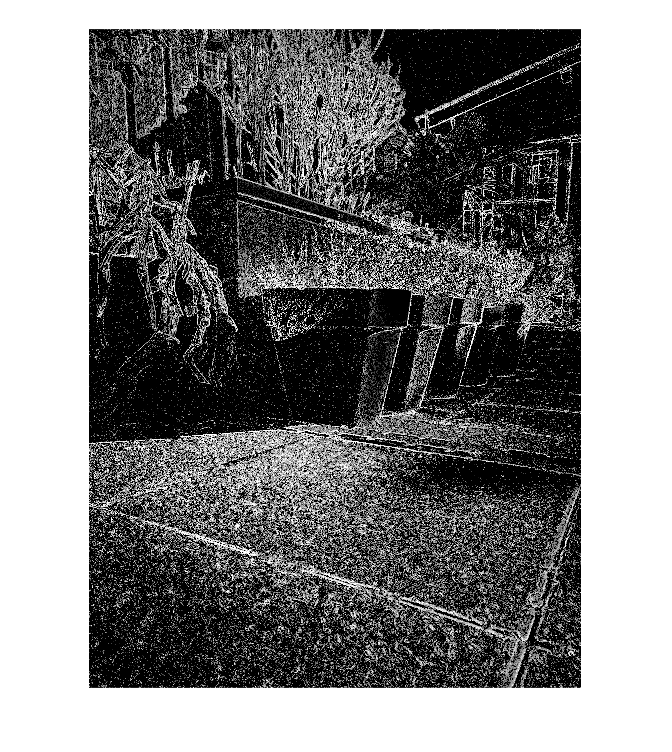

imshow(lin2rgb(gather(0.5 .* (CosFactorOG - 1.0))));

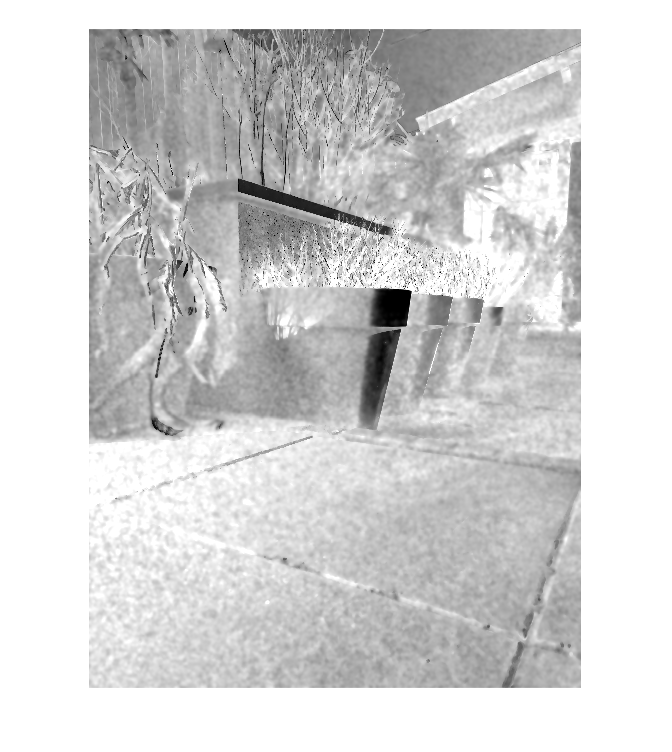

imshow(lin2rgb(gather(0.5 .* (CosFactor - 1.0))));

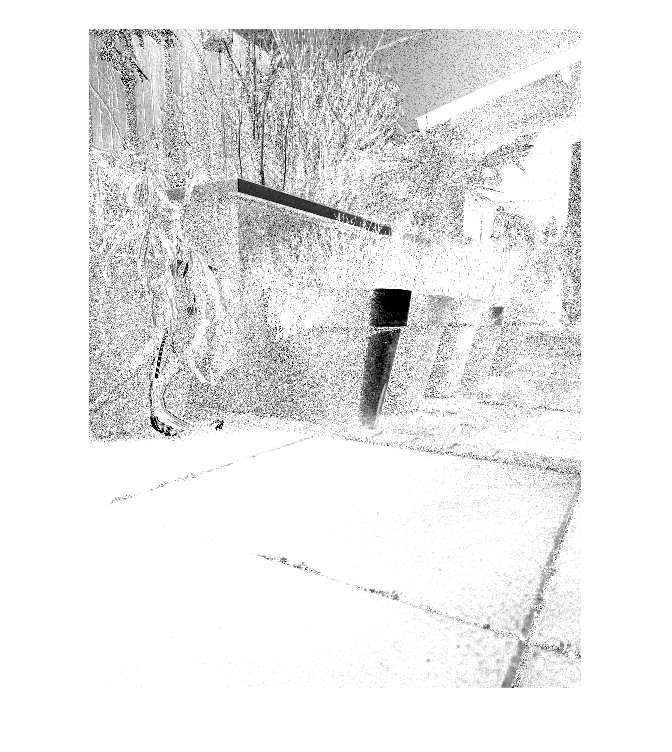

imshow(lin2rgb(gather(0.5 .* (CosFactor_Max - 1.0))));

Specular = CosFactor .* CosRGB;
Diffuse = max(0.0, MeanRGB - Specular);
for c = 1:3
    %Diffuse(:, :, c) = medfilt2(Diffuse(:, :, c));
end
Specular = max(0.0, MeanRGB - Diffuse);

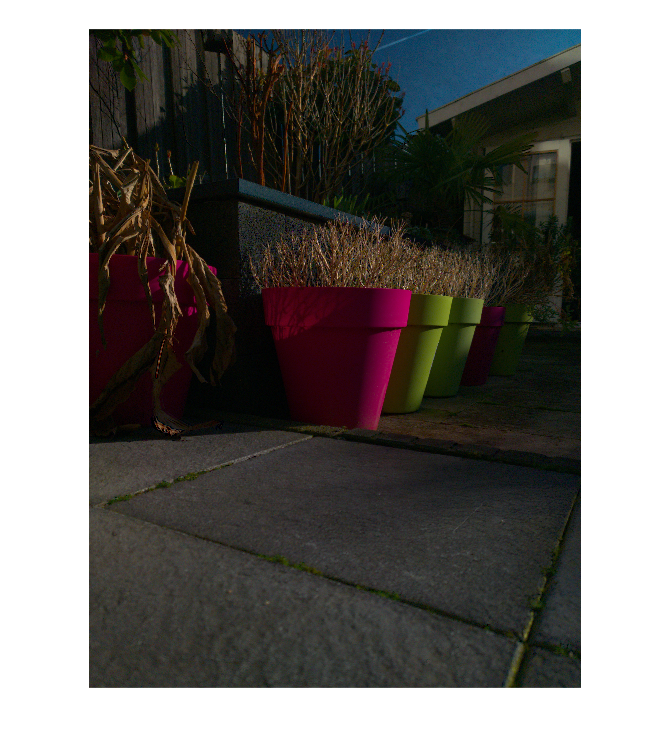

imshow(lin2rgb(gather(Diffuse)));

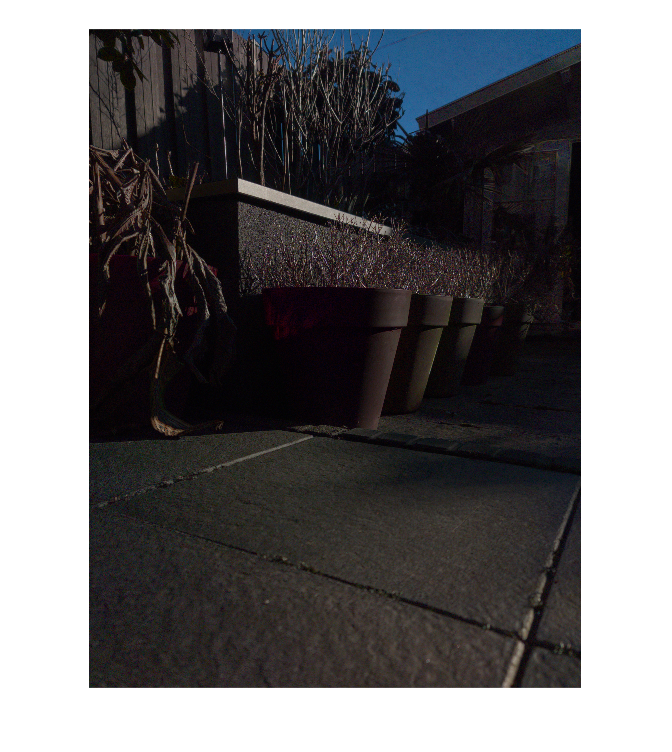

imshow(lin2rgb(gather(Specular)));

imshow(lin2rgb(gather(tonemapimage(Diffuse, 0.4, 1.0))));

% [Y, X, ~] = size(MeanRGB);
% DifFactor = zeros([Y X 3]);
% CosFactor = zeros([Y X 3]);
% 
% A = ones([25 2]);
% b = zeros([25 1]);
% 
% for y = 3:Y-2
%     for x = 3:X-2
%         for c = 1:3
%             
%             % Fill matrix.
%             for i = 1:25
%                 y2 = y + floor((i - 1) / 5) - 2;
%                 x2 = x + mod(i - 1, 5) - 2;
%                 A(i, 2) = CosRGB(y2, x2, c);
%                 b(i) = MeanRGB(y2, x2, c);
%             end
%             
%             ATA = A' * A;
%             ATb = A' * b;
%             
%             res = ATA \ ATb;
%             
%             DifFactor(y, x, c) = res(1);
%             CosFactor(y, x, c) = res(2);
%         end
%     end
% end
% 
% clear y;
% clear x;
% 
% imshow(lin2rgb(DifFactor));
% imshow(lin2rgb(CosFactor));

% Specular = max(CosFactor, [], 3) .* CosRGB;
% Diffuse = MeanRGB - Specular;
% 
% min(max(CosFactor, [], 3), [], [1 2])
% 
% imshow(lin2rgb(Diffuse));
% imshow(lin2rgb(Diffuse + Specular));
% imshow(lin2rgb(Specular));

% imshow(lin2rgb(DifFactor .* 1 + CosFactor .* CosRGB));
% imshow(lin2rgb(DifFactor .* 1));
% imshow(lin2rgb(CosFactor .* CosRGB));
% % imshow(lin2rgb(0.5 .* CosFactor));

% min(CosFactor, [], [1 2 3])
% imshow(lin2rgb(0.5 .* max(CosFactor, [], 3)));

% imshow(lin2rgb(MeanRGB(:, :, 1)));
% imshow(lin2rgb(CosRGB(:, :, 1)));
% imshow(lin2rgb(DifFactor(:, :, 1)));
% imshow(lin2rgb(CosFactor(:, :, 1)));